clear; clc
r=0.26; L=35/100; M=51/1000; g=9.81;
km=24.2e-3;
kb=km;
Ra=2.21;
Nr=4.5;
ku=12;
f=0.0079;
J=0.0048;
c=0.000685;

s=tf('s');
q=2*M*L^2*s^2+6*c*s+3*M*L*g;
Py=180/pi*(ku*km*Nr/Ra)*q/(s*((J+M*r^2)*s+f)*q-1.5*(M*L*r)^2*s^4+s*kb*km*Nr^2/Ra*q);
Pt=-3*M*L*r*s^2/q;
F=(30^2)/(s^2+1.6*30*s+30^2);
Cy=  (0.4048*s^2 + 2.823*s + 2.757)/(10*s^2 + 237.6*s);

Pau=minreal(Pt*Py*Cy/(1+Py*Cy))

Pau =
 
                        -269.9 s^4 - 1882 s^3 - 1838 s^2
  -----------------------------------------------------------------------------
  s^6 + 26.58 s^5 + 371.3 s^4 + 3341 s^3 + 1.473e04 s^2 + 7.156e04 s + 6.936e04
 
Continuous-time transfer function.



Py

Py =
 
               0.9356 s^2 + 0.3077 s + 39.33
  -------------------------------------------------------
  0.0001563 s^4 + 0.0004412 s^3 + 0.009696 s^2 + 0.0154 s
 
Continuous-time transfer function.



Pt

Pt =
 
            -0.01392 s^2
  --------------------------------
  0.01249 s^2 + 0.00411 s + 0.5253
 
Continuous-time transfer function.



Py=zpk(Py)

Py =
 
   5983.8 (s^2 + 0.3289s + 42.04)
  ---------------------------------
  s (s+1.64) (s^2 + 1.182s + 60.07)
 
Continuous-time zero/pole/gain model.



Pt=zpk(Pt)

Pt =
 
        -1.1143 s^2
  -----------------------
  (s^2 + 0.3289s + 42.04)
 
Continuous-time zero/pole/gain model.



Pau=zpk(Pau)

Pau =
 
                   -269.91 s^2 (s+5.799) (s+1.174)
  -----------------------------------------------------------------
  (s+13.42) (s+1.192) (s^2 + 1.255s + 32.17) (s^2 + 10.72s + 134.8)
 
Continuous-time zero/pole/gain model.



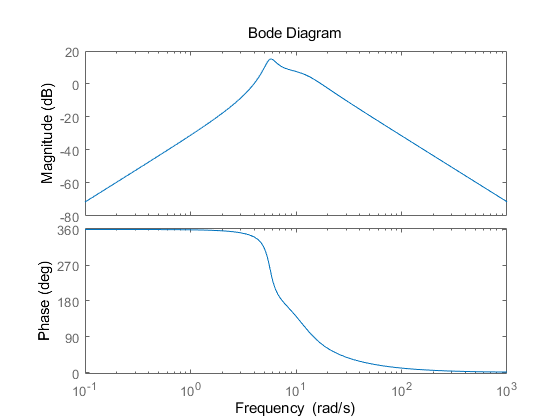

bode(Pau)

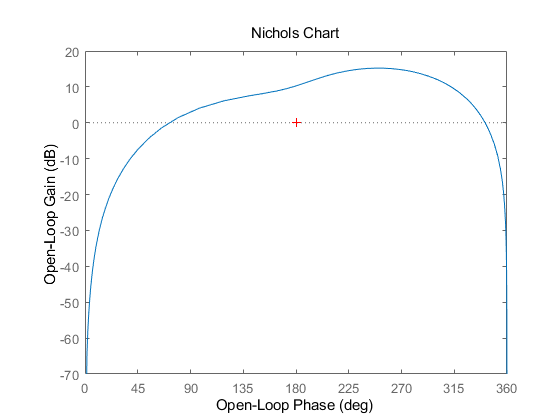

nichols(Pau)

Ctheta=pidstd(-1,0.6,0)*200/(s+200)

Ctheta =
 
  -200 s - 333.3
  --------------
   s^2 + 200 s
 
Continuous-time transfer function.






T=feedback(Pau,Ctheta)

T =
 
                     -269.91 s^3 (s+1.174) (s+5.799) (s+200)
  -----------------------------------------------------------------------------
  s (s+201.5) (s+8.811) (s+1.193) (s^2 + 1.405s + 15.28) (s^2 + 13.72s + 428.9)
 
Continuous-time zero/pole/gain model.



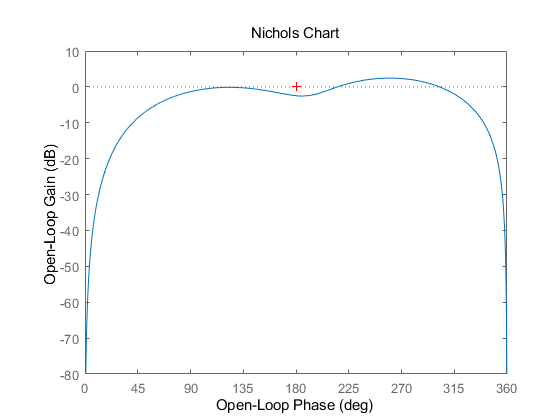

nichols(T)

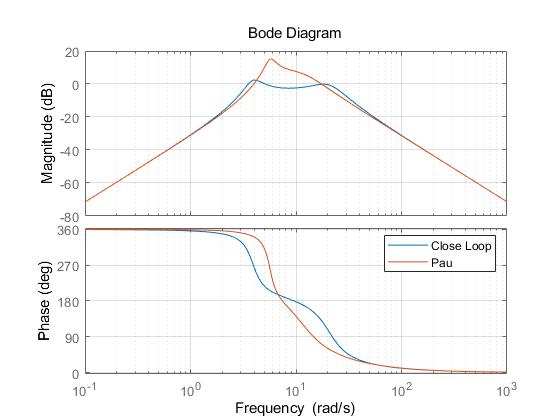

[mag w]=bode(T); bode(T); hold on; bode(Pau); hold off; legend('Close Loop','Pau');grid on

[mag w]=bode(Ctheta); mag=mag2db(mag)

mag = mag(:,:,1) =

   44.4371


mag(:,:,2) =

   33.9811


mag(:,:,3) =

   32.6459


mag(:,:,4) =

   31.3108


mag(:,:,5) =

   29.9761


mag(:,:,6) =

   28.6418


mag(:,:,7) =

   27.3081


mag(:,:,8) =

   25.9751


mag(:,:,9) =

   24.6432


mag(:,:,10) =

   24.4526


mag(:,:,11) =

   23.3126


mag(:,:,12) =

   21.9840


mag(:,:,13) =

   20.6580


mag(:,:,14) =

   19.3356


mag(:,:,15) =

   18.0179


mag(:,:,16) =

   16.7066


mag(:,:,17) =

   15.4040


mag(:,:,18) =

   14.1130


mag(:,:,19) =

   12.8373


mag(:,:,20) =

   11.5821


mag(:,:,21) =

   10.3535


mag(:,:,22) =

    9.1594


mag(:,:,23) =

    8.0093


mag(:,:,24) =

    6.9140


mag(:,:,25) =

    5.8853


mag(:,:,26) =

    5.7723


mag(:,:,27) =

    4.9351


mag(:,:,28) =

    4.0743


mag(:,:,29) =

    3.3109


mag(:,:,30) =

    2.6495


mag(:,:,31) =

    2.0896


mag(:,:,32) =

    1.6263


mag(:,:,33) =

    1.2510


mag(:,:,34) =

    0.9527


mag(:,:,35) =

    0.7193


mag(:,:,36) =

    0.53

w

w = w(:,:,1) =

   90.3409


w(:,:,2) =

   91.1362


w(:,:,3) =

   91.3251


w(:,:,4) =

   91.5452


w(:,:,5) =

   91.8020


w(:,:,6) =

   92.1013


w(:,:,7) =

   92.4503


w(:,:,8) =

   92.8570


w(:,:,9) =

   93.3310


w(:,:,10) =

   93.4050


w(:,:,11) =

   93.8832


w(:,:,12) =

   94.5262


w(:,:,13) =

   95.2747


w(:,:,14) =

   96.1453


w(:,:,15) =

   97.1569


w(:,:,16) =

   98.3308


w(:,:,17) =

   99.6908


w(:,:,18) =

  101.2626


w(:,:,19) =

  103.0736


w(:,:,20) =

  105.1515


w(:,:,21) =

  107.5228


w(:,:,22) =

  110.2095


w(:,:,23) =

  113.2261


w(:,:,24) =

  116.5745


w(:,:,25) =

  120.2389


w(:,:,26) =

  120.6773


w(:,:,27) =

  124.1817


w(:,:,28) =

  128.3413


w(:,:,29) =

  132.6343


w(:,:,30) =

  136.9616


w(:,:,31) =

  141.2186


w(:,:,32) =

  145.3073


w(:,:,33) =

  149.1454


w(:,:,34) =

  152.6730


w(:,:,35) =

  155.8529


w(:,:,36) =

  158.6691


w(:,:,37) =

  161.1214


w(:,:,38) =

  163.2211


w(:,:,39) =

  16

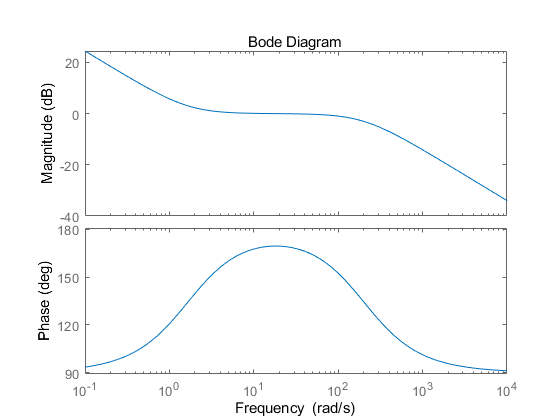

bode(Ctheta)

k0=load("k_0.mat");
k1=load('k_1.mat');

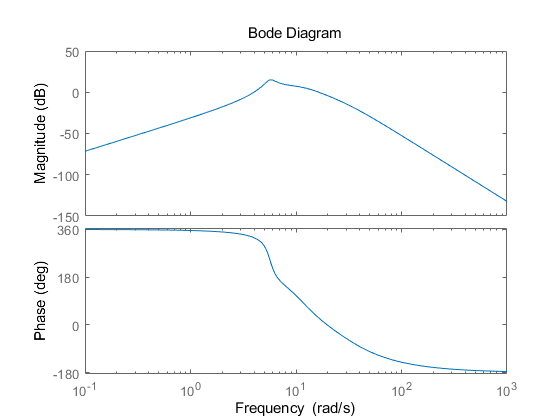

rt_o=F*Pau;
rt_c=F*feedback(Pau,Ctheta);
ry_o=rt_o/Pt;
ry_c=rt_c/Pt;

bode(rt_o)

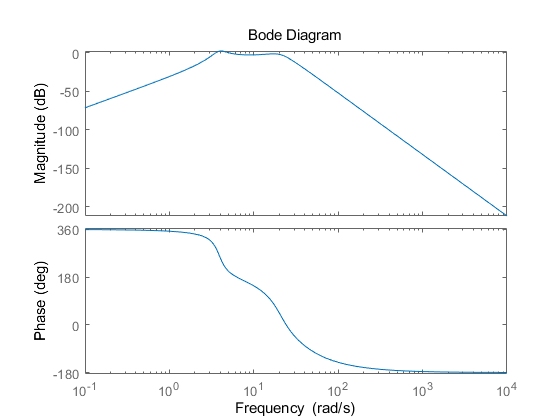

bode(rt_c)

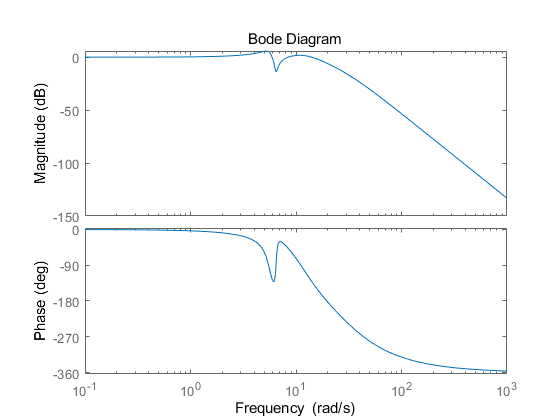

bode(ry_o)

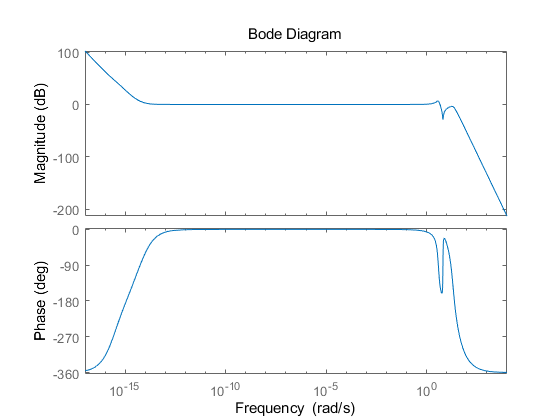

bode(ry_c)